# MACM 203 Assignment 3

## Preamble

In this question, we consider Conway's Game of Life.

In this assignment, you may modify Iain Haslam's code (see class notes), or write your own from scratch according to your preference.

## Part A: Glider speed

In class, we defined a *glider*, which is a configuration that travels diagonally across the grid. Initialize a glider as follows (white=alive, black=dead):

                        

What is the speed of the glider? Carefully define and assign units to the speed.

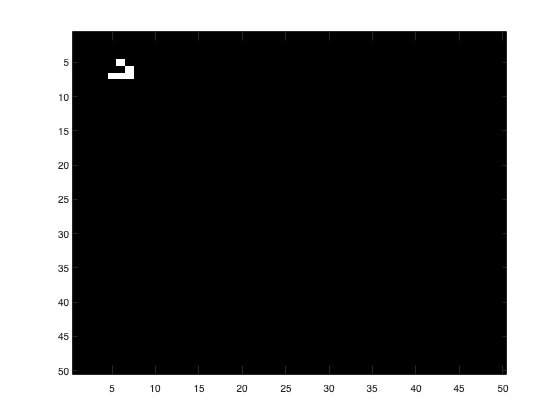

clf; clear all;

% life.m - Conway's Game of Life
% code by Iain Haslam
% https://www.exolete.com/life/
len=50; 
%GRID=int8(rand(len,len));

GRID = int8(zeros(len,len)); %signed 8 bin integer
                             % -128 to +127.
%GRID(5,4:6)=1; %Blinker
%GRID(5,4:6)=1;GRID(6,3:5)=1; %Toad
GRID(3,1:3)=1;GRID(2,3)=1;GRID(1,2)=1; %Glider
%GRID(5,5:8)=1;GRID(4,9)=1;GRID(3:4,5)=1; GRID(2,6)=1;GRID(2,9)=1; %Lightweight spaceship	
%GRID(10,10:11)=1;GRID(11,11)=1; GRID(11,15:17)=1;GRID(9,16)=1;%Diehard	
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs

% gray(2) returns gray colormap with 2 colors
% black and white
% colormap map sets the colormap for the current figure to the specified predefined colormap.
colormap(gray(2)); 

for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

        Notice that there are 4 iterations before the glider returns to its initial shape (it is a cycle). Also notice that with each new cycle, the configuration has moved one cell right and one cell down (diagonal). So the the glider moves at a speed of $\frac{1\;\textrm{cell}\;\textrm{down}}{1\;\textrm{cell}\;\textrm{right}}$ per 4 generations, so the speed is $\frac{1}{4}\;\frac{\textrm{cells}}{\textrm{generation}}$.

## Part B: Glider collisions

In Conway's Game of Life, gliders can be initialized that are 0, 90, 180 or 270 degree rotations of the glider specified above. Experimentally determine and describe what happens when two such gliders collide. Find all possibilities.

### 0 and 90 degree rotations

% 0 and 90 degree rotation collision same x-coord
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(1:3,1:3)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    In this orientation, the gliders collide at a 45 degree angle and eventually achieve a stable state. If we look at when the y-coordinates meet, their x-coordinates are the same. This results in the gliders in a steady state pattern that looks like 4 groups of 4 rectangles attached at the corners in a somewhat floral shape.

% 0 and 90 degree rotation collision offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(2:4,1:3)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    In this scenario, the gliders are still initialized at 0 and 90 degrees orientations, and result in a recurring pattern. They are initialized to meet on a path offset by 1.

% 0 and 90 degree rotation collision offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(1:3,3:5)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    Here, the gliders are initialized at 0 and 90 degrees, and their path is offset by 2 cells and have the same result as having no offset (flower-like pattern steady state).

% 0 and 90 degree rotation collision offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(1:3,3:5)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

% 0 and 90 degree rotation collision offset at back
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(2:4,4:6)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    Here, the 0 and 90 rotation gliders collide after being intialized on a path offset by 3 cells, with the 90 degree rotation at the back and it appears to result in a stady state of a 2x2 rectangle.

% 0 and 90 degree rotation collision at back bottom
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(1:3,5:7)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    The gliders collide with the 90 degree glider hitting the back edge of the 0 degree glider. This results in a steady state of 2 2x2 rectangles.

% 0 and 90 degree rotation collision at
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GRID(1:3,6:8)=GLIDER_0;
GRID(17:19,1:3)=GLIDER_90;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders collide with the 90 degree glider hitting the back of the 0 degree glider. These result in one steady state and another orientation flipping rectangle.

### 0 and 180 degree rotations

% 0 and 180 degree rotation collision corner
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_180 = rot90(rot90(GLIDER_0));
GRID(1:3,1:3)=GLIDER_0;
GRID(8:10,8:10)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:25
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    Here the 0 and 180 degree gliders collide head on at their corners. The result is a steady state 2x2 rectangle.

% 0 and 180 degree rotation collision edge
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_180 = rot90(rot90(GLIDER_0));
GRID(1:3,1:3)=GLIDER_0;
GRID(8:10,7:9)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:25
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    The 0 and 180 gliders collide on an adjoining edge and appear to be mirror images of each other. The result is cancelling out and all cells are dead. 

### 0 and 270 degree rotation

% 0 and 270 degree rotation collision same y-coordinate
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270 = rot90(rot90(rot90(GLIDER_0)));
GRID(1:3,1:3)=GLIDER_0;
GRID(1:3,25:27)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These 0 and 270 gliders are initialized as 0 and 270 degrees and meet at their x-coordinate edge with the same y-coordinate. The result is the flower-like steady state.

% 0 and 270 degree rotation collision y-coord offset by one cell
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270 = rot90(rot90(rot90(GLIDER_0)));
GRID(1:3,1:3)=GLIDER_0;
GRID(2:4,25:27)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:50
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    The 0 and 270 gliders meet at their x-coordinate edge with an offset of one cell on the y-coordinate. The result is a continuously flipping rectangle.

% 0 and 270 degree rotation collision
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270 = rot90(rot90(rot90(GLIDER_0)));
GRID(1:3,1:3)=GLIDER_0;
GRID(3:5,25:27)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

The 0 and 270 gliders meet at their x-coordinate edge with an offset of 2 cells. The result is the flower-like arrangment steady state.

% 0 and 270 degree rotation collision
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270 = rot90(rot90(rot90(GLIDER_0)));
GRID(1:3,1:3)=GLIDER_0;
GRID(4:6,25:27)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These 0 and 270 gliders meet at their y-coordinate edge with one cell edge touching. The result is the continuosly flipping rectangle.

% 0 and 270 degree rotation collision
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270 = rot90(rot90(rot90(GLIDER_0)));
GRID(1:3,1:3)=GLIDER_0;
GRID(5:7,25:27)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:60
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These 0 and 270 gliders meet at the y-coordinate edge and result in 2 2x2 rectangles steady state.

% 0 and 270 degree rotation collision
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270 = rot90(rot90(rot90(GLIDER_0)));
GRID(1:3,1:3)=GLIDER_0;
GRID(6:8,25:27)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders collide at the y-coordinate edge and result in one steady state shape and one continuosly flipping rectangle.

### 90 and 180 degree rotations

% 90 and 180 degree rotation no offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_180 = rot90(GLIDER_90)
GRID(17:19,1:3)=GLIDER_90;
GRID(17:19,14:16)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:50
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These 2 gliders collide at a 45 degree angle with a direct path. The result is a continuously flipping rectangle.

% 90 and 180 degree rotation offset 1
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_180 = rot90(GLIDER_90)
GRID(17:19,1:3)=GLIDER_90;
GRID(16:18,14:16)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:50
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These rectangles have their path offset by one cell and when they collide, the flower-like pattern arises.

% 90 and 180 degree rotation offset 2
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_180 = rot90(GLIDER_90)
GRID(17:19,1:3)=GLIDER_90;
GRID(15:17,14:16)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:80
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders have their paths offset by 2 cells and when they collide, the reslt is a continuosly flipping rectangle.

% 90 and 180 degree rotation offset 3
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_180 = rot90(GLIDER_90)
GRID(17:19,1:3)=GLIDER_90;
GRID(14:16,14:16)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:80
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders have their paths offset by 3 cells and when they collide, result in a steady state of 2 2x2 rectangles.

% 90 and 180 degree rotation offset 4
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_180 = rot90(GLIDER_90)
GRID(17:19,1:3)=GLIDER_90;
GRID(13:15,14:16)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:80
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders have their paths offset by 4 cells and when they collide, result in a continuously flipping rectangle and a steady state pattern.

### 90 and 270 degree rotation

% 90 and 270 degree rotation collision no offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_270 = rot90(rot90(GLIDER_90));
GRID(17:19,1:3)=GLIDER_90;
GRID(10:12,8:10)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:25
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders travel on the same line and collide head on and result in a 2x2 rectangle steady state.

% 90 and 270 degree rotation collision no offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_90 = rot90(GLIDER_0);
GLIDER_270 = rot90(rot90(GLIDER_90));
GRID(17:19,1:3)=GLIDER_90;
GRID(10:12,9:11)=GLIDER_270;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:25
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    When the paths of the two gliders are offset by one cell, the result is cancelling out, so there are only dead cells on the grid.

### 180 and 270 degree rotations

% 180 and 270 degree rotation collision no offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_180 = rot90(rot90(GLIDER_0));
GLIDER_270 = rot90(GLIDER_180);
GRID(10:12,15:17)=GLIDER_270;
GRID(26:28,15:17)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    There is no offset in their paths and these gliders collide on the full edge and the result is the flower-like arrangement steady state.

% 180 and 270 degree rotation collision one cell offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_180 = rot90(rot90(GLIDER_0));
GLIDER_270 = rot90(GLIDER_180);
GRID(10:12,15:17)=GLIDER_270;
GRID(26:28,14:16)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:50
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders have their paths offset by one cell and the result after colliding is the continuously flipping rectangle.

% 180 and 270 degree rotation collision two offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_180 = rot90(rot90(GLIDER_0));
GLIDER_270 = rot90(GLIDER_180);
GRID(10:12,15:17)=GLIDER_270;
GRID(26:28,13:15)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:50
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders have their paths offset by two cells and the result is the flower-like arrangement steady state.

% 180 and 270 degree rotation collision three offset
clf; clear all;
len=50; 
GRID = int8(zeros(len,len));

% Glider
GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_180 = rot90(rot90(GLIDER_0));
GLIDER_270 = rot90(GLIDER_180);
GRID(10:12,15:17)=GLIDER_270;
GRID(26:28,12:14)=GLIDER_180;
up=[2:len 1]; down=[len 1:len-1]; %periodic BCs
colormap(gray(2)); 
for i=1:100
    % sum over neighbours
    neighbours=GRID(up,:)+GRID(down,:)+GRID(:,up)+GRID(:,down)+...
        GRID(up,up)+GRID(up,down)+GRID(down,up)+GRID(down,down);
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2); % image(C) displays the data in array C as an image using the figure's colormap
    pause(0.2);     % 0.2 second pause
end

    These gliders have their paths offset by three cells and the result is a continuously flipping rectangle.

## Part C: Boundary conditions

In class, our cellular automata considered periodic boundary conditions. Suppose that we instead apply *mirror boundary conditions* (we introduce artifical cells outside the domain and populate these cells by mirroring across the boundary at every generation).

Describe what happens in the case when gliders collide with the boundary. Find all possibilites.

clf; clear all;
% create mirror boundary conditions with depth 1
% corners will reflect in all directions
% ex. cell at upper-left corner will reflect north, west, and north-west
% so there will be 3 mirrored cells for the one corner cell
len=50; 
GRID = int8(zeros(len,len));
GRID_m = int8(zeros(len+2,len+2));
colormap(gray(2));

for i=1:100
    % populate ghost cells for mirror boundary
    % top mirror
    GRID_m(1,1)=GRID(1,1);              % top row left corner
    GRID_m(1,2:end-1)=GRID(1,:);        % top row except corners
    GRID_m(1,end)=GRID(1,end);          % top row righ corner
    % bottom mirror
    GRID_m(end,1)=GRID(end,1);          % bottom row left corner
    GRID_m(end,2:end-1)=GRID(end,:);    % bottom row except corners
    GRID_m(end,end)=GRID(end,end);
    % left mirror (no corner)         
    GRID_m(2:end-1,1)=GRID(:,1);        % left side except corners
    % right mirror (no corner)
    GRID_m(2:end-1,end)=GRID(:,end);    % right side except corners
    % inside
    GRID_m(2:end-1,2:end-1)=GRID;       % original grid

    % sum over neighbours
    neighbours = GRID_m(2:end-1,3:end)+GRID_m(1:end-2,3:end)+...
        GRID_m(1:end-2,2:end-1)+GRID_m(1:end-2,1:end-2)+...
        GRID_m(2:end-1,1:end-2)+GRID_m(3:end,1:end-2)+...
        GRID_m(3:end,2:end-1)+GRID_m(3:end,3:end);
    % populate updated grid
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2);
    pause(0.2);
end

### Glider collide with mirror boundary not at edge

clf; clear all;
% create mirror boundary conditions with depth 1
% corners will reflect in all directions
% ex. cell at upper-left corner will reflect north, west, and north-west
% so there will be 3 mirrored cells for the one corner cell
len=50; 
GRID = int8(zeros(len,len));
GRID_m = int8(zeros(len+2,len+2));
colormap(gray(2));

GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GRID(40:42,5:7)=GLIDER_0;

for i=1:100
    % populate ghost cells for mirror boundary
    % top mirror
    GRID_m(1,1)=GRID(1,1);              % top row left corner
    GRID_m(1,2:end-1)=GRID(1,:);        % top row except corners
    GRID_m(1,end)=GRID(1,end);          % top row righ corner
    % bottom mirror
    GRID_m(end,1)=GRID(end,1);          % bottom row left corner
    GRID_m(end,2:end-1)=GRID(end,:);    % bottom row except corners
    GRID_m(end,end)=GRID(end,end);
    % left mirror (no corner)         
    GRID_m(2:end-1,1)=GRID(:,1);        % left side except corners
    % right mirror (no corner)
    GRID_m(2:end-1,end)=GRID(:,end);    % right side except corners
    % inside
    GRID_m(2:end-1,2:end-1)=GRID;       % original grid

    % sum over neighbours
    neighbours = GRID_m(2:end-1,3:end)+GRID_m(1:end-2,3:end)+...
        GRID_m(1:end-2,2:end-1)+GRID_m(1:end-2,1:end-2)+...
        GRID_m(2:end-1,1:end-2)+GRID_m(3:end,1:end-2)+...
        GRID_m(3:end,2:end-1)+GRID_m(3:end,3:end);
    % populate updated grid
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2);
    pause(0.2);
end

    The glider approaches the bottom boundary edge and we see that after colliding, it reaches a state of 3 flipping rectangles. By symmetry, the other 3 boundary edges will have the same result.

### Glider colliding with corner interaction

clf; clear all;
% create mirror boundary conditions with depth 1
% corners will reflect in all directions
% ex. cell at upper-left corner will reflect north, west, and north-west
% so there will be 3 mirrored cells for the one corner cell
len=50; 
GRID = int8(zeros(len,len));
GRID_m = int8(zeros(len+2,len+2));
colormap(gray(2));

GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270=rot90(rot90(GLIDER_0));
GRID(5:7,5:7)=GLIDER_270;

for i=1:25
    % populate ghost cells for mirror boundary
    % top mirror
    GRID_m(1,1)=GRID(1,1);              % top row left corner
    GRID_m(1,2:end-1)=GRID(1,:);        % top row except corners
    GRID_m(1,end)=GRID(1,end);          % top row righ corner
    % bottom mirror
    GRID_m(end,1)=GRID(end,1);          % bottom row left corner
    GRID_m(end,2:end-1)=GRID(end,:);    % bottom row except corners
    GRID_m(end,end)=GRID(end,end);
    % left mirror (no corner)         
    GRID_m(2:end-1,1)=GRID(:,1);        % left side except corners
    % right mirror (no corner)
    GRID_m(2:end-1,end)=GRID(:,end);    % right side except corners
    % inside
    GRID_m(2:end-1,2:end-1)=GRID;       % original grid

    % sum over neighbours
    neighbours = GRID_m(2:end-1,3:end)+GRID_m(1:end-2,3:end)+...
        GRID_m(1:end-2,2:end-1)+GRID_m(1:end-2,1:end-2)+...
        GRID_m(2:end-1,1:end-2)+GRID_m(3:end,1:end-2)+...
        GRID_m(3:end,2:end-1)+GRID_m(3:end,3:end);
    % populate updated grid
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2);
    pause(0.2);
end

    This glider interacts with the corner boundary and results in a 2x2 rectangle steady state. By symmetry, this also occurs at the other corners.

clf; clear all;
% create mirror boundary conditions with depth 1
% corners will reflect in all directions
% ex. cell at upper-left corner will reflect north, west, and north-west
% so there will be 3 mirrored cells for the one corner cell
len=50; 
GRID = int8(zeros(len,len));
GRID_m = int8(zeros(len+2,len+2));
colormap(gray(2));

GLIDER_0 = int8(zeros(3,3));
GLIDER_0(3,1:3)=1;GLIDER_0(2,3)=1;GLIDER_0(1,2)=1;
GLIDER_270=rot90(rot90(GLIDER_0));
GRID(1:3,1:3)=GLIDER_270;

for i=1:50
    % populate ghost cells for mirror boundary
    % top mirror
    GRID_m(1,1)=GRID(1,1);              % top row left corner
    GRID_m(1,2:end-1)=GRID(1,:);        % top row except corners
    GRID_m(1,end)=GRID(1,end);          % top row righ corner
    % bottom mirror
    GRID_m(end,1)=GRID(end,1);          % bottom row left corner
    GRID_m(end,2:end-1)=GRID(end,:);    % bottom row except corners
    GRID_m(end,end)=GRID(end,end);
    % left mirror (no corner)         
    GRID_m(2:end-1,1)=GRID(:,1);        % left side except corners
    % right mirror (no corner)
    GRID_m(2:end-1,end)=GRID(:,end);    % right side except corners
    % inside
    GRID_m(2:end-1,2:end-1)=GRID;       % original grid

    % sum over neighbours
    neighbours = GRID_m(2:end-1,3:end)+GRID_m(1:end-2,3:end)+...
        GRID_m(1:end-2,2:end-1)+GRID_m(1:end-2,1:end-2)+...
        GRID_m(2:end-1,1:end-2)+GRID_m(3:end,1:end-2)+...
        GRID_m(3:end,2:end-1)+GRID_m(3:end,3:end);
    % populate updated grid
    GRID = neighbours==3 | GRID & neighbours==2;
    image(GRID*2);
    pause(0.2);
end

    This glider starts off interacting with the mirror boundary and results in all cells killed. By symmetry, this also occurs at the other corners.